# 1.2 命令窗运行入门

1.2.1 **命令窗简介**

        命令窗默认地位于MATLAB桌面的右下方。可获得**几何独立**的命令窗。

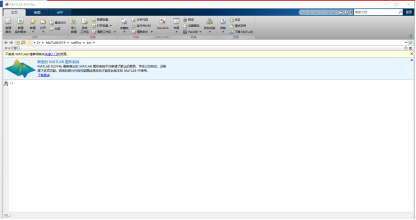

图 1.2-1  命令窗被最大化的桌面

1.2.2   **最简单的计算器使用法**

【例1.3-1】求$\left[12+2.4 \sin \frac{\pi}{6}\right] \div 3.25^{2}$的运算结果。

(12+2*sin(pi/6))/3.25^2

ans = 1.2308

〖说明〗

-   是“命令输入提示符”

- 一条命令输入结束后，必须按** [Enter] **键，那命令才被执行。

- 由于本例输入命令是“不含赋值号的表达式”，所以计算结果被赋给

- MATLAB的一个**默认变量**“ans”。它是英文“answer”的缩写。

【例1.3-2】“续行输入”法

        本例演示：由于命令太长，或出于某种需要，输入命令行必须多行书写时，

        该如何处理？

S=1-1/2+1/3-1/4+ ...
    1/5-1/6+1/7-1/8

S = 0.6345

〖说明〗

- 用三个或三个以上的“.”表示续行。

- 运行结果赋给变量S并被保存在 MATLAB 的工作区中，以备后用

            若不对S  重新赋值或clear用清除，该变量会一直保存在工作内存中直到本MATLAB被关闭

1.2.3   **数值、变量和表达式**

## **1.** **数值的记述**

（1）变量赋值——数值运算的前提

            如计算a*sin(b)前，先对变量a和b分别赋值。

 （2）输入数值的M码表述

            MATLAB的数值采用习惯的十进制表示，可以带小数点或正负号

            也可用科学计数形式。以下十进制浮点数都合法：

                    3，	   -99，	 0.001， 	9.456，	  1.3e-3， 	+4.5e33， -4.5e12

- 采用IEEE浮点算法的计算机上，数值数据默认采用

**            占用****64****位（****Bit****）内存的****“****双精度**Double**”****表示**，其相对精度为eps=2-52

**            要高度重视计算机浮点数离散的本质**

- Double型可以精确到16位十进制数，即以**16****位有效数字**进行运算。

- 但屏幕显示格式是可设定的，见表1.3-1

- 默认输出结果由尾数含4位有效小数构成。

## **2.** **变量命名规则**

- **变量名、函数名是对字母大小写敏感的**。

            如：变量myvar和Myvar表示两个不同的变量。

            sin是MATLAB定义的正弦函数名，但SIN，Sin等都不是。

- **变量名的第一个字符必须是英文字母**

**            最多可包含****63****个字符（英文、数字和下连符）**，**下述变量名是合法的**

            myvar201，my_var_201

- **变量名中**不得包含**空格、标点、运算符****，但可以包含****下连符**。

            my,var201由于逗号的分隔，表示的就不是一个变量名。

- 用户变量名不应与MATLAB关键词、变量名、函数名、文件夹名相同

iskeyword VarName  %判断变量名VarName是否与关键词相同结果为0时，表示不同。

ans = logical
   0


iskeyword('str')

ans = logical
   0


iskeyword         %列出所有关键词

ans = 20×1 cell 数组
    {'break'     }
    {'case'      }
    {'catch'     }
    {'classdef'  }
    {'continue'  }
    {'else'      }
    {'elseif'    }
    {'end'       }
    {'for'       }
    {'function'  }
    {'global'    }
    {'if'        }
    {'otherwise' }
    {'parfor'    }
    {'persistent'}
    {'return'    }
    {'spmd'      }
    {'switch'    }
    {'try'       }
    {'while'     }



exist VarName      %判断是否与变量名、函数名、文件夹名相同结果为0表示不同，结果为1-8表示相同

ans = 0

exist VarName kind

错误使用 exist
存在的第二个输入(可选)必须为 'var'、'builtin'、'class'、'dir' 或 'file'。

exist('VarName')
exist('VarName','kind')
% kind:
%  builtin(built-in functions)
%  class(classes)
%  dir(folder)
%  file(files or folders)
%  var(varibles)
%同样判断结果为0-8

## **3. MATLAB的特殊数值及专用变量名**

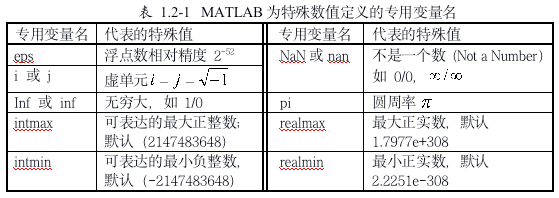

【说明】

- 建议：用户在编写命令和程序时，应尽可能不对表1.3-1所列预定义变量名重新赋值，以免产生混淆。 

            若重新赋值后，退出matlab 以及clear 恢复预定义值

- 被0 除是允许的。它不会导致程序执行的中断，只是在给出警告信息的同时，用一个特殊名称（如Inf，NaN）记述。

- 非数nan：0/0，∞/∞，0*∞，∞**-**∞; 测量数据处理中用来标识野点（非正常点）；数据可视化中用来剪裁图形。

format long e				 % 浮点数采用16位数字的科学记述格式
RMAd=realmax('double')	                 % 双精度类型时最大实数(默认)
RMAs=realmax('single')	                 % 单精度类型时最大实数
IMA64=intmax('int64')	                  %intmax(‘classname’), 整数类型最大正整数
IMA32=intmax				  %classname:int8,int16, int32（默认）,int64
IMA16=intmax('int16')
e1=eps				          %eps(x)返回与abs(x)最近的浮点数的距离,eps=eps(1)
e2=eps(10)		                  %常被粗略地用作双精度的相对精度
pi 					  %圆周率
format short

## **4.** **运算符和表达式**

（1） MATLAB的运算符

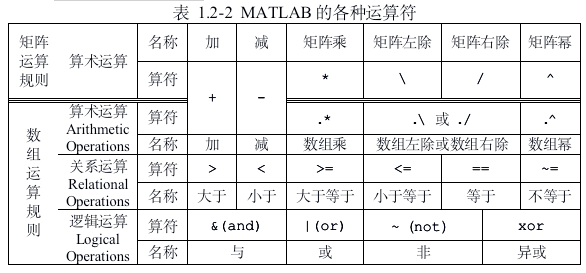

【说明】

- 因为MATLAB面向矩阵/数组设计，**标量**被看作的矩阵/数组。

- **数组运算符**比**矩阵运算符**多一个“小黑点”。

- **数组运算**的“乘、除、幂”规则与相应**矩阵运算****根本不同**。

            数组运算中，被运算数组中的每个元素是同时、平行地被作用；

            矩阵运算中，被运算矩阵是一个整体，组成矩阵的元素是相互关联的

（2） MATLAB的表达式

        MATLAB书写**表达式的规则**与“算式的单行手写规则”几乎完全相同。

- 表达式由已赋值变量、运算符和已经存在的函数名等组成。

- 表达式将按与常规相同的优先级自左至右执行运算。

- 优先级的规定：**指数运算最高，乘除运算次之，加减运算最低**。

- 括号可以改变运算的次序。

- 书写表达式时，赋值符“=”和运算符两侧允许有空格，以增加可读性。

X=(12+2*sin(pi/6))/3.25^2

## 5.面向复数设计的运算——MATLAB特点之一

**        MATLAB****的所有运算都是定义在复数域上的。**

**        优点****：**在进行运算时，不必像其他程序语言那样把实部、虚部分开处理。

        复数有两种表示方法：直角坐标和极坐标表示法。

        虚数用预定义变量 i 或 j 表示。

        $z=a+b i=r e^{i \theta}$ **直角坐标**表示和**极坐标**表示之间的转换命令：

`    real(z)`		       给出复数$z$的实部$a=r\text{ }\mathrm{cos}\theta \text{ }$ 。

`    imag(z)`		       给出复数$z$的虚部$b=r\text{ }\mathrm{sin}\theta \text{ }$。

`    abs(z)`		       给出复数$z$的模$\sqrt{a^2 +b^2 }$，实数取绝对值。

`    angle(z)`	       以**弧度为单位**给出复数$z$的幅角$\mathrm{arctan}\text{ }\frac{b}{a}$ 。

        复数是有序的实数对，复数与直角坐标平面上的点有一一对应的关系。

【例1.2-4】本例演示：正确的**复数输入**法；涉及复数表示方式的**基本命令**。

        复数表达$z_1 =4+3i,z_2 =1+2i,z_3 =2e^{\frac{\pi \text{ }}{6}i}$，及计算$z=\frac{z_1 z_2 }{z_3 }$

        (1) 经典教科书的直角坐标表示法

z1= 4 + 3i			 %合法，但建议少用或不用

**在这种格式中，3i是一个完整的虚数，不许“空格”存在。**

(2) 采用运算符构成的直角坐标表示法和极坐标表示法

z2 = 1 + 2 * i			%运算符构成的复数直角坐标表示法
z3=2*exp(i*pi/6)		%运算符构成的复数极坐标表示法
z=z1*z2/z3                   %定义在复数域上的运算

**表达式****中所有符号（包括****变量****名****、运算符****、****函数名****、数字、虚单元等）均不要留空格。因为空格被用作矩阵或数组元素之间的分隔符。**

（3）复数的实部、虚部、模和幅角计算

real_z=real(z)
image_z=imag(z)
magnitude_z=abs(z)
angle_z_radian=angle(z)				%弧度单位
angle_z_degree=angle(z)*180/pi		%度数单位  


【例1.2-5】图示复数$z_1 =4+3i,z_2 =1+2i$的和。

本例演示：

MATLAB的运算在复数域上进行；

复数加法的几何意义；

感受MATLAB的可视化能力。

z1=4+3*i;z2=1+2*i, z12=z1+z2;    %在一个物理行中，允许输入多条命令。
%但各命令间要用“分号”或“逗号”分开。
%命令后采用“分号”，使运算结果不显示。

%以下用于绘图
clf, hold on			%clf清空图形窗。逗号用来分隔两个命令。
plot([0,z1,z12],'-b','LineWidth',3)
plot([0,z12],'-r','LineWidth',3)
plot([z1,z12],'ob','MarkerSize',8)
hold off,
grid on,
axis equal
axis([0,6,0,6])
text(3.5,2.3,'z1')
text(5,4.5,'z2')
text(2.5,3.5,'z12')
xlabel('real')
ylabel('image')

## 6.面向数组和矩阵设计的运算——MATLAB特点之二

- 数组（Array）：标量数据被组织成矩形或长方体形的阵列集合

            数组可是多维的。二维数组是最基础最常用的数组。

            矩阵（Matrix）：在外形、元素排列和编址方面都与二维数组相同，

            但概念和运算规则截然不同。

- 一个标量数据被看作1*1的数组或矩阵。

            所有的数据都被存放在适当大小的数组中。

- MATLAB设计了两种基本运算：**数组运算矩阵运算**

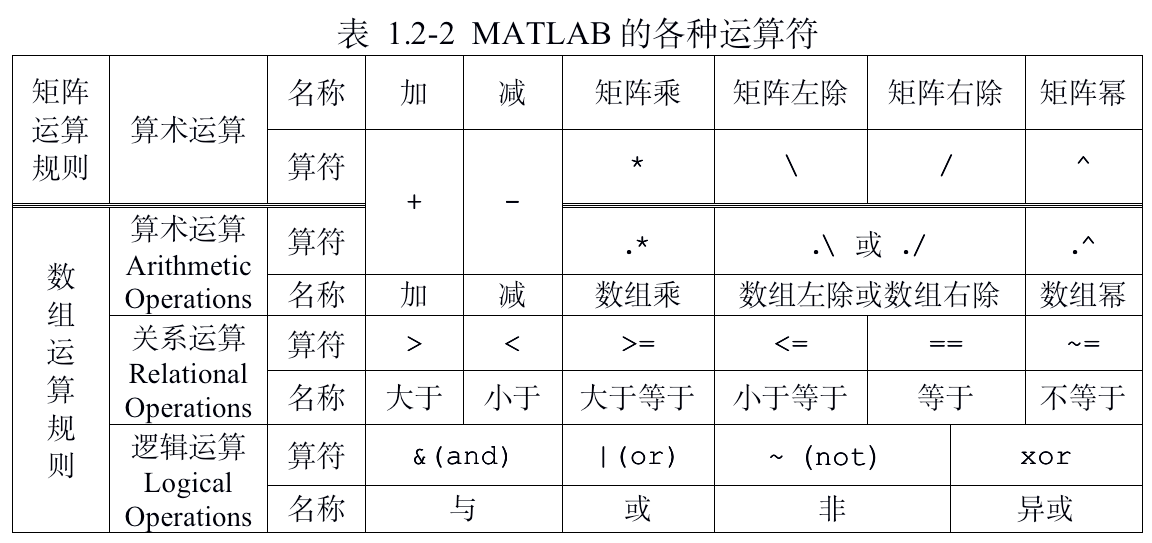

【例1.2-7】数组的输入法。所有标点符号必须是“**英文状态的符号**”。

**        二维数组输入的****三大要素****：** 

**        数组标识符****:** **  “****[ ]****”**

**        元素分隔符****：****空格****或****逗号****“ , ”**

**        数组****行间分隔符****：****分号****“ ; ”****或****“回车键**”

**        实数****数组**：可一行输入也可分行输入

AR=[1,2;3,4]  
AR1=[1 2;3 4]
AI=[1,4                 %“回车键”用来分隔数组中的行
3,4]                % 符合视觉习惯大数组也可采用此法
AI1=[3 4
5 6]

**复数数组：**

A=AR-AI*i	                    %实、虚部合成法
A1=[1-5*i,3-7*i;2-6*i,4-8*i]        %复元素组合法

〖说明〗

- 不必事先对数组维数及大小做任何说明，内存将自动配置。

- MATLAB**对字母大小写是敏感**的，如AR与 Ar,、aR、或ar 不同。

【例1.2-9】对复数数组$A=\left[\begin{array}{ll}{1-5 i} & {3-7 i} \\ {2-6 i} & {4-8 i}\end{array}\right]$进行求实部、虚部、模和幅角的运算。

        本例演示： MATLAB命令对数组元素“并行操作”的实质。

**（****1****）创建复数数组**

AR=[1,3;2,4];AI=[5,7;6,8];
A=AR-AI*i						%形成复数矩阵

**（2）求复数数组的实部和虚部**

A_real=real(A)
A_image=imag(A)  

**（3）求复数数组中各元素的模和幅角——循环法**

for m=1:2
    for n=1:2
      		Am1(m,n)=abs(A(m,n));
      		Aa1(m,n)=angle(A(m,n))*180/pi;	%以度为单位计算幅角
    end
end
Am1,Aa1

**（4）求复数数组中各元素的模和幅角——直接法**

Am2=abs(A)
Aa2=angle(A)*180/pi 

〖说明〗

- 函数real, imag, abs, angle是同时、并行地作用于数组的每个元素。

                对4个元素运算所需的时间与对单个元素所需时间在同一数量级。

                这有利于**运算速度的提高**。这是“**数组化**”运算的一种形式。

- 本例给出了循环法求各元素模和幅角的命令。这是**低****效**的计算方法。

                对许多编程语言来说，**不得不**采用“**标量****+****循环**”处理方式来解本例。

**        记住：**对于MATLAB来说，应该尽量**摒弃****“****标量****+****循环****”**处理，**采用****“****数组****化****”**处理方式。

A=rand(200,200);          %200*200数组
tic
for m=1:200
for n=1:200
		Am1(m,n)=abs(A(m,n));
		Aa1(m,n)=angle(A(m,n))*180/pi;	%以度为单位计算幅角
	end
end
toc  

tic
AM1=abs(A);
AA1=angle(A)*180/pi;  toc


【例1.2-11】 复数矩阵**的乘积和**复数数组**的乘积**


$$A=\left[\begin{array}{ll}{1-5 i} & {3-7 i} \\ {2-6 i} & {4-8 i}\end{array}\right]$$
  
$$\mathrm{B}=\left[\begin{array}{ll}{3+2 i} & {2+6 i} \\ {5+3 i} & {4-2 i}\end{array}\right]$$


A=[1-5*i,3-7*i;2-6*i,4-8*i] %
B=[3+2*i,2+6*i;5+3*i,4-2*i] %注意标点符号的作用
C=A*B 	                 %矩阵乘法
D=A.*B						  %数组乘法  

**〖说明〗**

- 当数组被赋予“变换”属性时，二维数组就被称为矩阵。只有当两个矩阵的“**内维大小相等**”时，矩阵乘法才能进行。

- 数组运算是数组的每个元素同时、并行地进行的，数组规模必须相同

- 在其他许多编程语言中，**矩阵****数组****乘法不得不依赖****“循环”**进行

【例1.2-10】画出衰减振荡曲线$y=e^{-\frac{t}{3}} \mathrm{sin}\text{ }3t$，$t$的取值范围是

        本例演示：展示**数组运算的优点**；展示MATLAB的**可视化**能力。

t=0:pi/50:4*pi;			             % 定义自变量t的取值数组
y=exp(-t/3).*sin(3*t);	       % 典型的“数组化”处理形式
plot(t,y,'-r','LineWidth',2);	      % 绘制曲线
axis([0,4*pi,-1,1]),
xlabel('t'),ylabel('y') 
